clc; clear; close all;

% -----------------------------
% Cargar datos como tabla
% -----------------------------
filename = 'Five_times_Kinematics_HT_Query_MATLAB.xlsx';
numericData = readtable(filename);  % Esto carga los nombres de las variables también

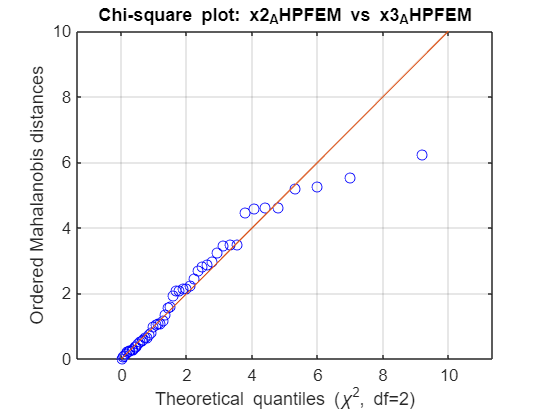

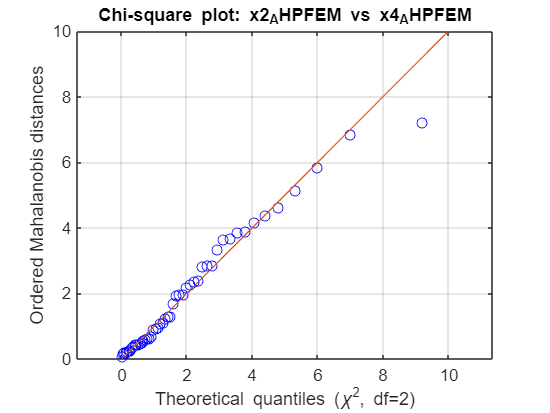

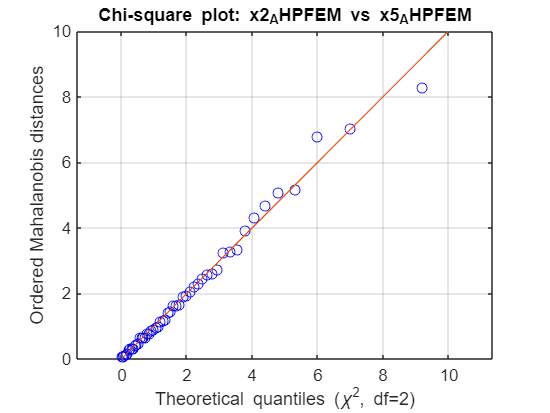

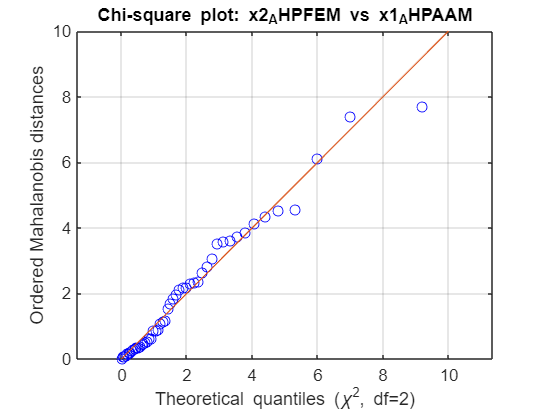

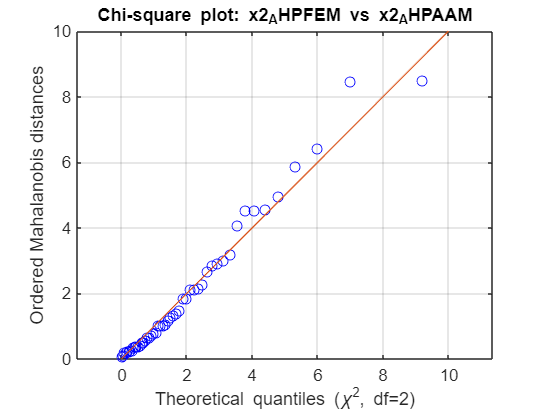

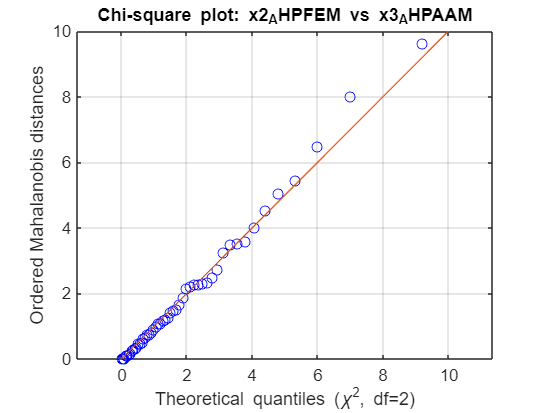

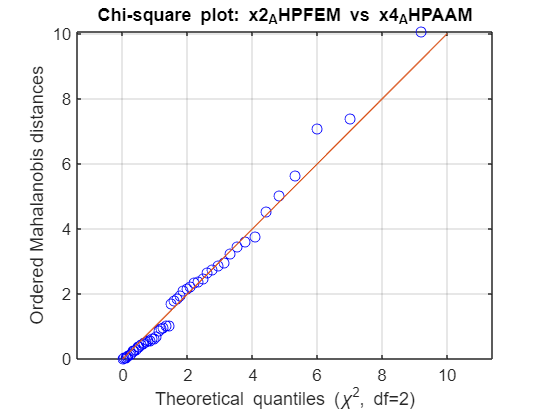

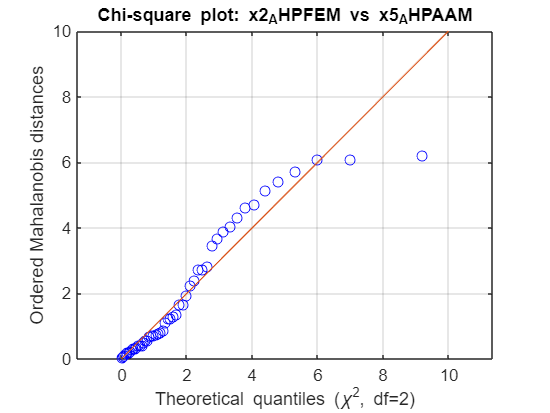


X = numericData{:,:};  % Extraer solo los datos numéricos
[n, p] = size(X);

% -----------------------------
% Chi-square plot
% Comparar variable 8 con todas las siguientes (desde la 9)
% -----------------------------
dim_interes = 29;

for j = 30:p
    % Extraer los datos de las columnas como vectores
    X_sub = [X(:, dim_interes), X(:, j)];  % n x 2

    % Calcular vector de medias y matriz de covarianza
    mean_vec = mean(X_sub);
    cov_mat = cov(X_sub);
    inv_cov = inv(cov_mat);

    % Calcular distancias de Mahalanobis
    mahal_dist = zeros(n, 1);
    for i = 1:n
        diff = X_sub(i, :) - mean_vec;
        mahal_dist(i) = diff * inv_cov * diff';
    end

    % Cuantiles teóricos de chi-cuadrado con 2 grados de libertad
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % Obtener nombres de las variables
    varName_i = numericData.Properties.VariableNames{dim_interes};
    varName_j = numericData.Properties.VariableNames{j};

    % Graficar Chi-square plot
    figure;
    plot(chi2_q, sort(mahal_dist), 'bo');
    hold on;
    refline(1, 0);  % línea identidad
    xlabel('Theoretical quantiles (\chi^2, df=2)');
    ylabel('Ordered Mahalanobis distances');
    title(['Chi-square plot: ', varName_i, ' vs ', varName_j]);
    axis equal;
    grid on;
end